# Solución analítica


clear
clc

syms Theta_1(t) Theta_2(t) Theta_3(t) R_1(t) t
syms r_1 r_1y r_2 r_3
syms theta_1 theta_2 theta_3 
syms V_r omega_1 omega_2 omega_3 
syms a_r alpha_1 alpha_2 alpha_3

Vr_2=0.075

Vr_2 =    0.075000000000000


Vr_3=0.17

Vr_3 =    0.170000000000000


Vr_1y=0.045

Vr_1y =    0.045000000000000


Vtheta_2=0

Vtheta_2 =      0


Vomega_2=0

Vomega_2 =      0


Valpha_2=0

Valpha_2 =      0



Fc=sin(Theta_1)*R_1-r_1y;
fc=formula(subs(Fc,[Theta_1, R_1],[theta_1, r_1]));

Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5);
fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5);
fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

D2FcDt2=diff(DFcDt);
D2FxDt2=diff(DFxDt);
D2FyDt2=diff(DFyDt);
F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));


SolR_1=solve(fc,r_1)

$$SolR\_1 = \frac{r_{\mathrm{1y}}}{\sin\left(\theta_{1}\right)}$$

SolTheta_1=solve(simplify(subs(fx,r_1,SolR_1),"Steps",15),theta_1)

$$SolTheta\_1 = \mathrm{acot}\left(\frac{r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)}{r_{\mathrm{1y}}}\right)$$

SolTheta_3=solve(fy-fc,theta_3);
SolTheta_3=SolTheta_3(2)

$$SolTheta\_3 = \pi -\mathrm{asin}\left(\frac{r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)}{r_{3}}\right)$$



SolOmega_3=solve(F3-F2,omega_3)

$$SolOmega\_3 = -\frac{\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)}{r_{3}\,\cos\left(\theta_{3}\right)}$$


SolOmega_1=solve(F3,omega_1);
SolOmega_1=simplify(SolOmega_1,"Steps",10)

$$SolOmega\_1 = -\frac{V_{r}\,\tan\left(\theta_{1}\right)}{r_{1}}$$


SolV_r=solve(subs(F1,omega_1,SolOmega_1),V_r);
SolV_r=simplify(SolV_r,"Steps",10)

$$SolV\_r = -\cos\left(\theta_{1}\right)\,\left(\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)+\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\right)$$


SolAlpha_3=solve(F6-F4,alpha_3);
SolAlpha_3=simplify(SolAlpha_3,"Steps",20)

$$SolAlpha\_3 = \frac{r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)}{r_{3}\,\cos\left(\theta_{3}\right)}$$


SolAlpha_1=solve(F4,alpha_1);
SolAlpha_1=simplify(SolAlpha_1,"Steps",20)

$$SolAlpha\_1 = {\omega_{1}}^{2}\,\tan\left(\theta_{1}\right)-\frac{2\,V_{r}\,\omega_{1}+a_{r}\,\tan\left(\theta_{1}\right)}{r_{1}}$$


SolA_r=solve(subs(F5,alpha_1,SolAlpha_1),a_r);
SolA_r=simplify(SolA_r,"Steps",20)

$$SolA\_r = r_{1}\,{\omega_{1}}^{2}-r_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-\alpha_{2}\,r_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)$$



SolR_1=subs(SolR_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolTheta_1=subs(SolTheta_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolTheta_3=subs(SolTheta_3,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolV_r=subs(SolV_r,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolOmega_1=subs(SolOmega_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolOmega_3=subs(SolOmega_3,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolA_r=subs(SolA_r,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolAlpha_1=subs(SolAlpha_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolAlpha_3=subs(SolAlpha_3,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);


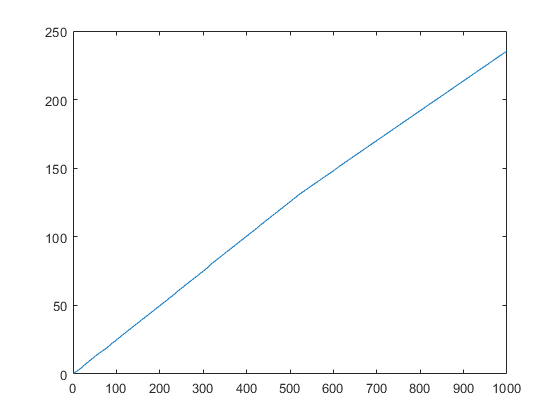


Tabla_Cinematica=readtable("Perfil_cinematica.txt","Delimiter"," ");
for i=1:length(Tabla_Cinematica.Tiempo) 
    Sol=Fanalitica(SolR_1,SolTheta_1,SolTheta_3,SolV_r,SolOmega_1,SolOmega_3,SolA_r,SolAlpha_1,SolAlpha_3,Tabla_Cinematica.Posicion(i),Tabla_Cinematica.Velocidad(i),Tabla_Cinematica.Aceleracion(i));
    ValoresSolucion_NR(i,:)=Sol;
end

Tabla_Cinematica.R_1=ValoresSolucion_NR(:,1);

Tabla_Cinematica.theta_1=ValoresSolucion_NR(:,2);
Tabla_Cinematica.theta_3=ValoresSolucion_NR(:,3);
Tabla_Cinematica.V_1=ValoresSolucion_NR(:,4);
Tabla_Cinematica.omega_1=ValoresSolucion_NR(:,5);
Tabla_Cinematica.omega_3=ValoresSolucion_NR(:,6);
Tabla_Cinematica.a_1=ValoresSolucion_NR(:,7);
Tabla_Cinematica.alpha_1=ValoresSolucion_NR(:,8);
Tabla_Cinematica.alpha_3=ValoresSolucion_NR(:,9);
writetable(Tabla_Cinematica,'ResultadosAnaliticos.txt','delimiter',' ', 'WriteVariableNames', true)


tablaNR = 1000×13 table
     Tiempo      Aceleracion    Velocidad      Posicion        R_1       theta_1     theta_3        V_1         omega_1       omega_3          a_1         alpha_1     alpha_3 
    _________    ___________    __________    __________    _________    ________    _______    ___________    __________    __________    ___________    _________    ________

            0            0               0             0    -0.099672    -0.46842    2.8737               0             0             0              0            0           0
    0

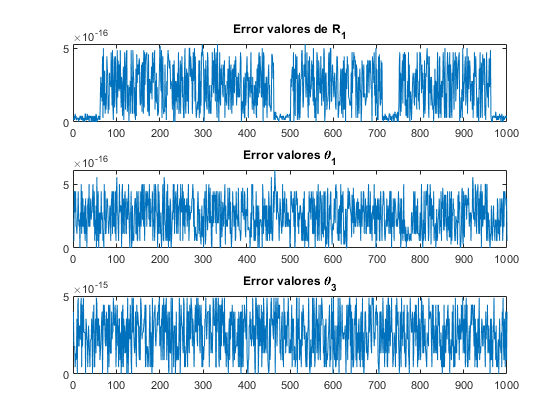

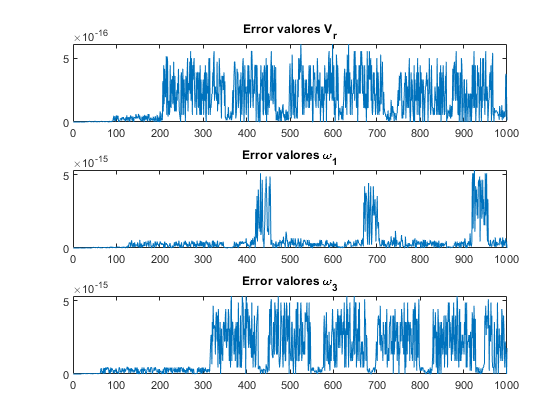

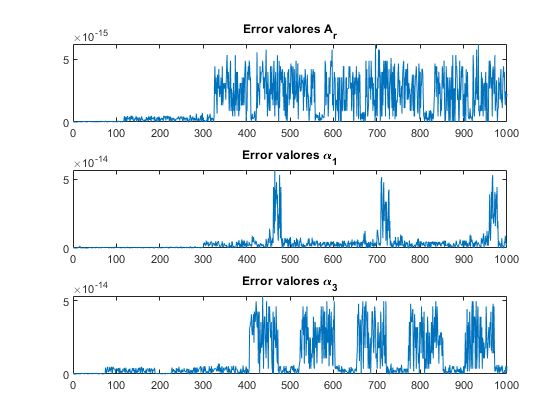

function solAnalitica=Fanalitica(SolR_1,SolTheta_1,SolTheta_3,SolV_r,SolOmega_1,SolOmega_3,SolA_r,SolAlpha_1,SolAlpha_3,Vtheta_2,Vomega_2,Valpha_2)

syms r_1 theta_1 theta_2 theta_3 V_r omega_1 omega_2 omega_3 a_r alpha_1 alpha_2 alpha_3
Vtheta_3=double(subs(SolTheta_3,theta_2,Vtheta_2));
Vtheta_1=double(subs(SolTheta_1,[theta_2,theta_3],[Vtheta_2,Vtheta_3]));
Vr_1=double(subs(SolR_1,theta_1,Vtheta_1));
Vomega_3=double(subs(SolOmega_3,[theta_2,theta_3,omega_2],[Vtheta_2,Vtheta_3,Vomega_2]));
Vv_r=double(subs(SolV_r,[theta_1,theta_2,theta_3,omega_2,omega_3],[Vtheta_1,Vtheta_2,Vtheta_3,Vomega_2,Vomega_3]));
Vomega_1=double(subs(SolOmega_1,[r_1,theta_1,V_r],[Vr_1,Vtheta_1,Vv_r]));
Valpha_3=double(subs(SolAlpha_3,[theta_2,theta_3,omega_2,omega_3,alpha_2],[Vtheta_2,Vtheta_3,Vomega_2,Vomega_3,Valpha_2]));
Va_r=double(subs(SolA_r,[r_1,theta_1,theta_2,theta_3,omega_1,omega_2,omega_3,alpha_2,alpha_3],[Vr_1,Vtheta_1,Vtheta_2,Vtheta_3,Vomega_1,Vomega_2,Vomega_3,Valpha_2,Valpha_3]));
Valpha_1=double(subs(SolAlpha_1,[r_1,theta_1,V_r,omega_1,a_r],[Vr_1,Vtheta_1,Vv_r,Vomega_1,Va_r]));
solAnalitica=[Vr_1,Vtheta_1,Vtheta_3,Vv_r,Vomega_1,Vomega_3,Va_r,Valpha_1,Valpha_3];
end

